## Generate a Fourier series from 2 to 4 function pieces

Made by [Slushee](https://slushee.dev/) (Pol Fernàndez Corella)

#### Number of pieces

pieces_n = 4;           % The number of pieces you want to join for the fourier series

The values on unused pieces will be ignored

#### Piece 1

f1 = @(t) 1;            % Input the first function you want to take a chunk from
f1_start_point = 0;     % X value of the start of the chunk
f1_end_point = 1;       % X value of the end of the chunk

#### Piece 2

f2 = @(t) 2;            % Input the second function you want to take a chunk from
f2_start_point = 1;     % X value of the start of the chunk
f2_end_point = 2;       % X value of the end of the chunk

#### Piece 3

f3 = @(t) 3;            % Input the third function you want to take a chunk from
f3_start_point = 2;     % X value of the start of the chunk
f3_end_point = 3;       % X value of the end of the chunk

#### Piece 4

f4 = @(t) 4;            % Input the fourth function you want to take a chunk from
f4_start_point =  3;    % X value of the start of the chunk
f4_end_point = 4;       % X value of the end of the chunk

#### Calculation requeriments

harmonic_n = 100;         % Number of harmonics to calculate for the Fourier series
harmonic_power_n = 10;   % Number of harmonics to use to calculate the average power.

#### Display parameters

graph_left = 3;         % How many cycles to the left of the origin you want to graph
graph_right = 3;        % How many cycles to the right of the origin you want to graph

Function definition

% oldparam = sympref ('HeavisideAtOrigin', 1);
u = @(t) heaviside(t);

if pieces_n == 2
    T = f2_end_point - f1_start_point;

    fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point));
    f = @(t) fT(t - T*floor((t - f1_start_point) / T));

    end_point = f2_end_point;
elseif pieces_n == 3
    T = f3_end_point-f1_start_point;

    fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point)) + f3(t).*(u(t - f3_start_point) - u(t - f3_end_point));
    f = @(t) fT(t - T*floor((t - f1_start_point) / T));

    end_point = f3_end_point;
else
    T = f4_end_point - f1_start_point;

    fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point)) + f3(t).*(u(t - f3_start_point) - u(t - f3_end_point)) + f4(t).*(u(t - f4_start_point) - u(t - f4_end_point));
    f = @(t) fT(t - T*floor((t - f1_start_point) / T));

    end_point = f4_end_point;
end

Parameter initialization

w = 2*pi/T;
a_n = zeros(1, harmonic_n + 1);
b_n = zeros(1, harmonic_n + 1);
a_m = zeros(1, harmonic_n + 1);
phi = zeros(1, harmonic_n + 1);
c = zeros(1, harmonic_n + 1);

Calculation of coeficients $a_n, \ a_m, \ b_n, \ c, \  \varphi$

for n = 0 : harmonic_n
    if pieces_n == 2
        a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*cos(n * w * t), f2_start_point, f2_end_point);
        b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*sin(n * w * t), f2_start_point, f2_end_point);    
    elseif pieces_n == 3
        a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*cos(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*cos(n * w * t), f3_start_point, f3_end_point);
        b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*sin(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*sin(n * w * t), f3_start_point, f3_end_point);
    else
        a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*cos(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*cos(n * w * t), f3_start_point, f3_end_point) + (2/T) * integral(@(t)f4(t).*cos(n * w * t), f4_start_point, f4_end_point);
        b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*sin(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*sin(n * w * t), f3_start_point, f3_end_point) + (2/T) * integral(@(t)f4(t).*sin(n * w * t), f4_start_point, f4_end_point);
    end

    if abs(a_n(n+1)) < 5*10^(-15)
        a_n(n+1) = 0;
    end
             
    if abs(b_n(n+1)) < 5*10^(-15)
        b_n(n+1) = 0;
    end

    c(n+1) = ( a_n(n+1) - 1j*b_n(n+1) ) / 2;    
    a_m(n+1) = sqrt( (a_n(n+1))^2 + (b_n(n+1))^2 );
    phi(n+1) = angle( a_n(n+1) - b_n(n+1)*1j );
end

Partial sum until the nth harmonic of the fourier series

S = @(t) a_n(1)/2;     
for n = 1 : harmonic_n      
    S = @(t) S(t) + a_n(n+1)*cos(n*w*t) + b_n(n+1)*sin(n*w*t);
end

Calculation of average power and amplitude

stem(0:1:harmonic_n, 2*abs(c))

f2 = @(t) f(t).^2;
if pieces_n == 2
    P = 1 / T * integral(f2, f1_start_point, f2_end_point);
elseif pieces_n == 3
    P = 1 / T * integral(f2, f1_start_point, f3_end_point);
else 
    P = 1 / T * integral(f2, f1_start_point, f4_end_point);
end

P_k = (a_n(1) / 2)^2;

for n = 2 : harmonic_power_n + 1
    P_k = P_k + (1/2) * (a_m(n))^2;
end

stdout_1 = "Average power after [ "+ harmonic_power_n + " ] harmonics = " + P;
stdout_2 = "Percentage of the total average power = " +  (P_k/P)*100 + " %";

Plotting the functions

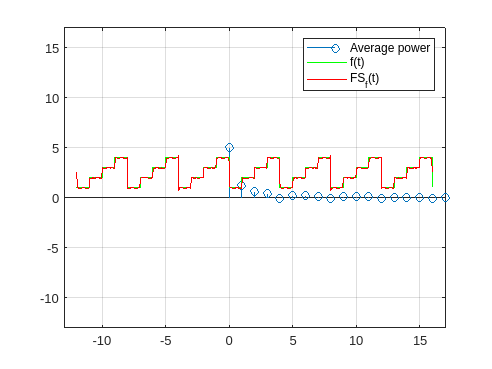

hold on

fplot(f, [f1_start_point - graph_left * T, end_point + graph_right * T], 'g')
I = linspace(f1_start_point - graph_left * T, end_point + graph_right * T, 650);

axis([-(T*graph_left)-1 (T*(graph_right+1))+1 min(I)-1 max(I)+1])
plot(I, S(I), 'r')
grid on
legend(["Average power", "f(t)", "FS_f(t)"])

figure

disp(stdout_1);

Average power after [ 10 ] harmonics = 7.5


disp(stdout_2);

Percentage of the total average power = 99.2382 %



ns = (0:harmonic_n)';
var_table = table(ns, a_n', b_n', c', a_m',phi', 'VariableNames', {'n', 'a_n', 'b_n', 'c_n', 'amplitude', 'phase'});
disp(var_table);

     n         a_n           b_n                c_n              amplitude     phase 
    ___    ___________    _________    ______________________    __________    ______

      0              5            0            2.5+0i                     5         0
      1              0      -1.2732              0-0.63662i          1.2732    1.5708
      2              0     -0.63662              0-0.31831i         0.63662    1.5708
      3              0     -0.42441              0-0.21221i         0.42441    1.5708
      4              0            0              0+0i                     0         0
      5              0     -0.25465              0-0.12732i         0.25465    1.5708
      6              0     -0.21221              0-0.1061i          0.21221    1.5708
      7              